**Numerical Methods Final Exam 2022 - Solutions**

1. Three compression tests were carried out on a spring. In each test the displacement was measured at the same values of applied force.

The results were:

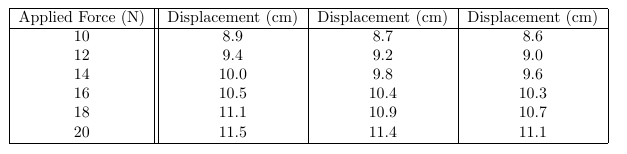

Plot the data then use linear regression to estimate the spring constant in kN/m. Plot the regression line on the same figure as the data.

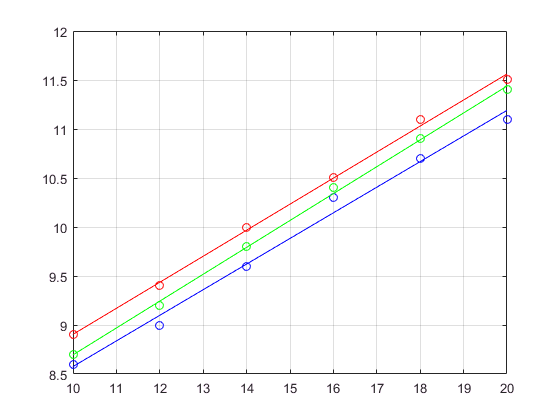

% Enter solution here

% Step 1: Create our data
n = [10 12 14 16 18 20];
cm1 = [8.9 9.4 10 10.5 11.1 11.5];
cm2 = [8.7 9.2 9.8 10.4 10.9 11.4];
cm3 = [8.6 9.0 9.6 10.3 10.7 11.1];

% Step 2: Let's plot the original data first
plot(n, cm1, 'ro');  % First test will be Red
hold on
grid on
plot(n, cm2, 'go');  % Second test will be Green
plot(n, cm3, 'bo');  % Third test will be Blue

xfit = linspace(min(n), max(n));

% Step 3: Next, we will do linear regression based on our data to find the best fit.
p1 = polyfit(n, cm1, 1);  % Grab linear coefficient. Note that linear must be degree 1
yfit1 = polyval(p1, xfit);  % Eqn.of the line using based on xfit points
plot(xfit, yfit1, 'r');

p2 = polyfit(n, cm2, 1);  % Same steps here, because we want to fit on the same figure
yfit2 = polyval(p2, xfit);
plot(xfit, yfit2, 'g');

p3 = polyfit(n, cm3, 1);
yfit3 = polyval(p3, xfit);
plot(xfit, yfit3, 'b');

2. The following data is to be fit to an equation of the form,

$$z = Ae^{Bx}y^C$$,

where A, B and C are constants. 

Use linearisation and regression to estimate the values of A, B, and C then use the fitted equation to estimate the value of z at the point $$(x,y) = (2.7, 3.3)$$.

Data:

% Enter solution here
% Step 1: Create Data
x_q2 = [1 2.2 3.5 4.5 5.6 7.8];
y_q2 = [0.3 1.7 3.4 5.8 8.8 11];
z_q2 = [0.31 0.71 0.37 0.22 0.10 0.01];

% Step 2: Solve to created fitted function | Multiple Linear Regression
% Logarithm Method because our function is in power equation
logX = log10(x_q2);
logY = log10(y_q2);
logZ = log10(z_q2);

z_mat = [ ones(size(logX))' logY' logZ' ];
z_q2_2 = [ logZ' ];

coef_mat = (z_mat'*z_mat)\(z_mat'*z_q2_2);
actual_a0 = 10.^coef_mat(1);
actual_a1 = coef_mat(2);
actual_a2 = coef_mat(3);

func_q2 = @(x,y) actual_a0 .* exp(actual_a1 .* x) .* y.^actual_a2;
fprintf('z = %f * e^(%f*x) * y^%f', actual_a0, actual_a1, actual_a2);

z = 1.000000 * e^(-0.000000*x) * y^1.000000

fprintf('Estimated (2.7, 3.3) = %f\n', func_q2(2.7, 3.3));

Estimated (2.7, 3.3) = 3.300000


3. Use a cubic **Lagrange** interpolant on the data below to estimate the following:

    a. The value of $f(x)$ when $x = 4.95$.

    b. The value of $x$ when $f(x) = 1.88$.

% Enter solution here

% Step 1: Create Data
x = [1.1 2.3 3.1 4.7 5.6 6.3 7.2];
y = [3.5 2.1 1.5 0.99 0.77 1.45 0.52];
xx = linspace(min(x), max(x));
graph = 0;

% Step 2: Interpolate using Lagrange's Method
for i = 1:length(x)
    u = 1;
    l = 1;
    for j = 1:length(x)
        if j ~= i
            u = u .* (xx - x(j));
            l = l * (x(i) - x(j));
        end
    end
    graph = graph + u / l * y(i);
end
scatter(x,y);
hold on
grid on
plot(xx, graph);

% Step 3: Estimated the value when x = 4.95
x_estimated = 4.95;
summation = 0;
for i=1:length(x)
    u = 1;
    l = 1;
    for j = 1:length(x)
        if j ~= i
            u = u .* (x_estimated - x(j));
            l = l * (x(i) - x(j));
        end
    end
    summation = summation + u / l * y(i);
end
fprintf('The estimated function value at x = 4.95 is %f\n', summation);

The estimated function value at x = 4.95 is 0.844687


plot(x_estimated, summation, 'bd');

% Step 4: Estimated the value of x when f(x) = 1.88 | Inverse Interpolation
p_q3 = polyfit(x, y, 3);
yy_q3 = polyval(p_q3, xx);
y_estimated = 1.88;

root_q3 = roots([p_q3(1) p_q3(2) p_q3(3) p_q3(4)-y_estimated]);
root_q3 = root_q3(imag(root_q3) == 0);
fprintf('The estimated x-value at f(x) = 1.88 is %f\n', root_q3);

The estimated x-value at f(x) = 1.88 is 2.448639


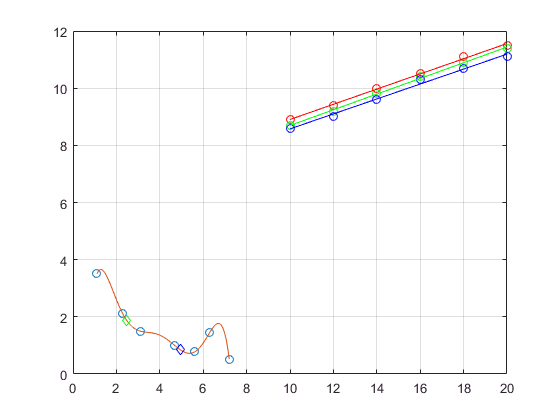

plot(root_q3, y_estimated, 'gd');

4. Approximate the following multiple integrals using any method (Matlab built-ins are recommended for highest accuracy):

    a. $\int\limits_{0}^{2}\int\limits_{y^3}^{4\sqrt{2y}} (x^2y - xy^2) \, dx \, dy$

    b. $\int\limits_{0}^{2}\int\limits_{0}^{4-x^2}\int\limits_{0}^{x} \sin(2z)e^{-x} \, dy \, dz \, dx$

% Enter solution here

% Step 1: Create a function
func1_q4 = @(x,y) ( ((x.^2).*y) - (x.*(y.^2)) );
solution1_q4 = integral2(func1_q4, 0, 2, @(y) y.^3, @(y) 4.*sqrt(2.*y));
fprintf('Approx.Integral of Func1 %f\n', solution1_q4);

Approx.Integral of Func1 -97.431457



% Step 2: Do for another (b.)
func2_q4 = @(x,y,z) sin(2.*z).*exp(-x);
solution2_q4 = integral3(func2_q4, 0, 2, 0, @(x) x, 0, 3);
fprintf('Approx.Integral of Func2 %f\n', solution2_q4);

Approx.Integral of Func2 0.011829


5. Answer the following questions for the integral:


$$\int\limits_{0}^{3\pi} (8 + \cos(x^2 - 3x)) \, dx$$


    a. Estimate the integral's value using 4 point Gauss-Legendre quadrature.

    b. What is the minimum number of partitions (value of $n$) needed to use Simpson's 1/3 rule to estimate the integral if we want the absolute approximate error to be less then 0.01? Demonstrate that your answer is correct.

% Enter solution here
% Step 1: Create Gauss-Legendre Quad.



6. The data below represents an objects position (m) measured at different times (s). Use a centred finite difference approach to estimate the time when the object experienced zero jerk.

**Reminder:** Jerk is the derivative of acceleration.

% Enter solution here
% Step 1: Create Data
t = [0 2 4 6 8 10 12 14 16];
s = [7.2 0.7040 0.3040 2.064 3.584 4 3.984 5.744 13.024];
h = 2;

% Step 2: Use Centred Finite Difference to estimate. Note = s' => v. v' => a. a' => J
j_cd = ( -3.984 + 12*4 - 39*3.584 + 56*2.064 - 39*0.304 + 12*0.704 - 7.2 )./(6*h.^4);

--- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.